# 1. Compute the confusion matrix and plot the ROC curve

## The data points and the corresponding labels:

label = [1 1 0 0 0 1 1 0 0 0 0 0];% /y_n
BTmp = [40 39 38.7 38.6 38.3 38.1 37.8 37.6 37.4 37.2 37 36.6]; %x_n

## Compute the confusion matrix:

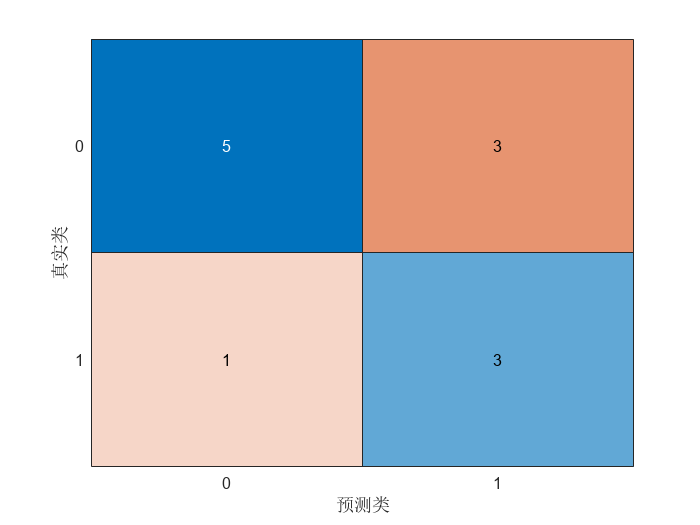

% Th is the threshold value
Th = 38;
% prediction 
pred = double(BTmp>38);
% compute the confusionchart
cm = confusionchart(label,pred);

## Plot the ROC curve:

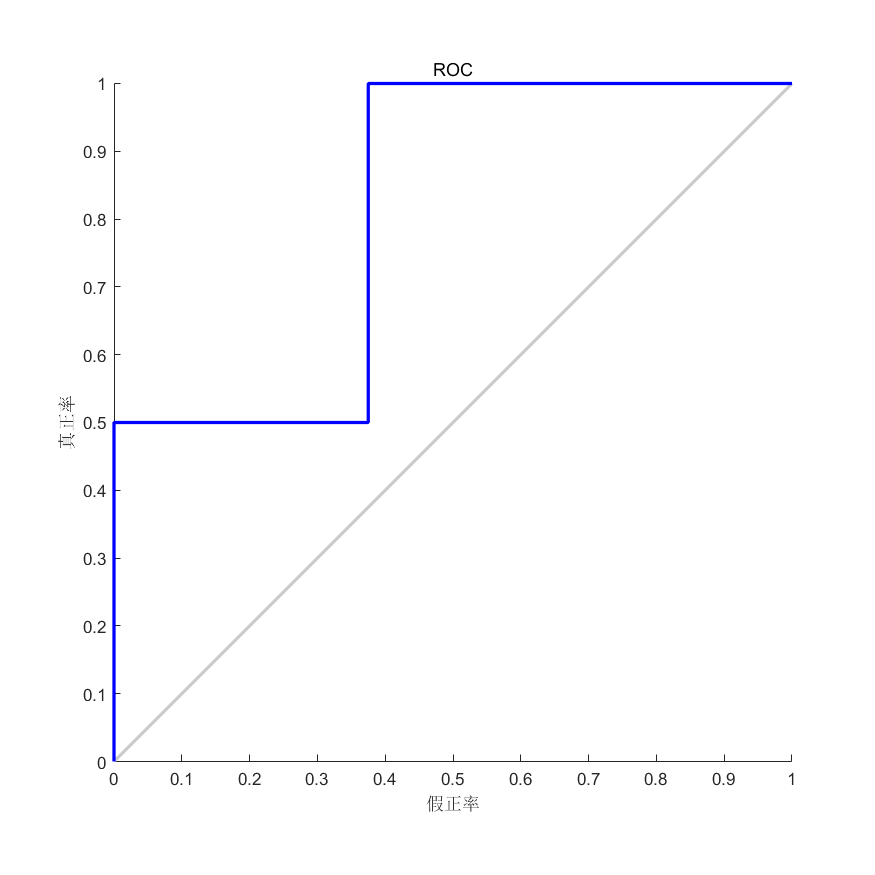

% normalize BTmp in [0,1]
BTmp_norm = (BTmp-36.6)/(40-36.6); % BTmp_norm [0,1]
% Plot the ROC curve
plotroc(label,BTmp_norm);